    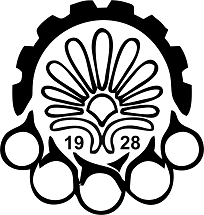

## Amirkabir University of Technology

(Tehran PolyTechnic )

## Turbulence Course Final Project 

Prepared by

## Hossein Sheikhshoaie

Supervisour 

## Dr. Ehsan Tavakoli

Mechanical Engineering Department

2022 spring

[Github code address](https://github.com/Hshsh2391/Turbulence-course-final-project/blob/main/turbulence_project.mlx)

# Problem specification

Direct numerical solution for fully developed turbulent chnnel flow, between two large horizontal planes with a relatively small Reynolds number (180) based on the frictional velocity ($u_\tau$) and half of the planes distance $\delta
$ has been done.  Frictional velocity has been defined as :


$$u_{\tau}\, =\, (\frac{\tau_w}{\rho})^{1/2}$$


Here some turbulence statistics will be evaluated and visualized.

## Flow geometry and coordinate system

Streamwise, normal to walls and spanwise direction has been called z, x and y, also their corresponding velocity components are w, u and v, respectively.  

As is evident in underneath figure, planes length and width are $4 \pi,\,2\pi$ respectively. Also channel height is 2. Note that $\delta
$ euals to one. 

128 and 256 nodes have been considered for spanwise and streamwise direction, sequentially.

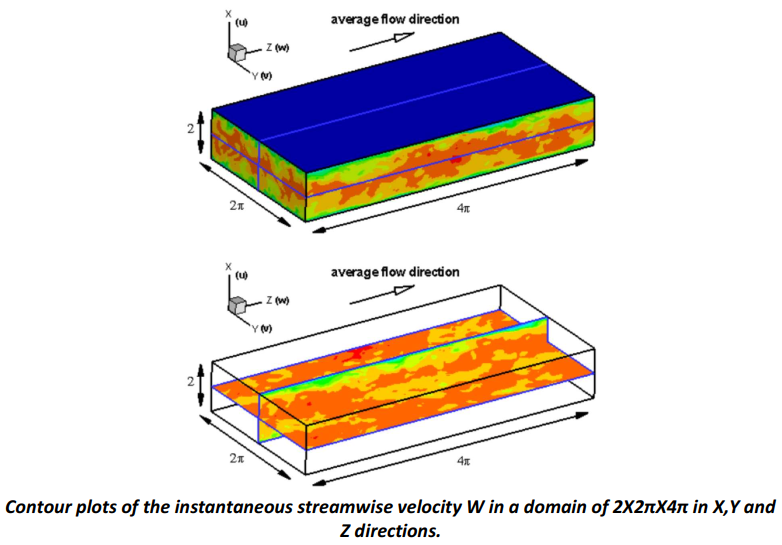

## Data sets

Two data sets are given;

 First is related to temporal records of U,V,W at a point located on the YZ plane which is shown above. 

Second contains spatial records of V and W on a generic YZ planes that is illustrated in the above figure. 

## Project objectives

1) PDFs (single, joint) of the available parameters and try whether you can distinguish the resemblance between these PDFs and the famous ones.

2) statistical moments (at least up to third order)

3) correlations (temporal and spatial, auto and cross correlations ,…)

4) Energy spectrum (1D temporal, and 1D-2D spatial)  

Project code is started here.

clc
clear
close all

First DNS temporal data are read from an excel file. 

%Temporal data extraction
tab_data = xlsread('UVW_Temporal_Data.xlsx', 'A2:C8193');
% Temporal normal to wall velocity component
u = tab_data(:,1);
% Temporal spanwise velocity component
v = tab_data(:,2);
% Temporal stream wise velocity component
w = tab_data(:,3);

% Spatial data extraction
tab_data_sp = xlsread('VW_YZ_Spatial_Data.xlsx', 'C3:D32770');
% Spatial spanwise velocity component
vsp = tab_data_sp(:,1);
% Spatial streamwise velocity component
wsp = tab_data_sp(:,2);

# Statistical centeral moments

Statistical moments are one of the primary tools in turbulence study, when there are not any powerful measurment tools. There are two available procedure to examine a turbulence phenomenon behavior. Using powerful measurment tools or statistical moments and pdfs. Statistical moments from first to fourth for both temporal and spatial data are calculated below.

First **mean value** of given velocity data will be eveluated. The mean value for a discrete data seris is calclculated by underneath formula :


$$\mu\,=\,\frac{1}{N}\Sigma\,\tilde{u} $$


**The first central moment**, which is calculated by below formula, of course **is zero**. 


$$\frac{1}{N}\Sigma\,\tilde{u}\, - \mu$$


**The** **second centeral moment**, mean-square departure from the mean value U is called the variance, that is defined as :


$$\sigma^2\, = \frac{1}{N} \Sigma\,(\tilde{u}\, - \, \mu)^2$$


The square root of the variance, $\sigma$, is the familiar standard deviation (rms amplitude). **The standard deviation** is the most convenient measure of the

width of PDFs, which is used to nondimensionalization of the higher order moments.   

The variance is not affected by any lack of symmetry about the origin in probebility density function, so the second moment is not enough. 

Here third centeral moment is defined as below :


$$\overline{u}^3 = \frac{1}{N} \Sigma\,(\tilde{u}\, - \, \mu)^3$$


This moment is nondimentionalized by ($\sigma^3$), which gives a dimensionless measure of the asymmetry. This is called** the skewness (S)** .


$$S = \frac {\overline{u}^3} {\sigma^3}$$


The skewness is positive if large negative values of $u^3
$ are not as frequent as large positive values of $u^3$. 

**The fourth moment**, that is nondimensionalized by $\sigma^4$, is called kurtosis or** flatness factor**. The value of the kurtosis is large if the PDF values in the tails of the probability density are relatively large.  

Flatness shows how frequently PDF values take place far away from the axis. Because the fourth moment is nondimensionalized with $\sigma^4$, K contains no information on the width of the density B(u).  

  
$$\overline{u}^4 = \frac{1}{N} \Sigma\,(\tilde{u}\, - \, \mu)^4 \quad ,\quad K= \, \frac{\overline{u}^4}{\sigma^4}$$


All the mentioned moments for each velocity component data set are calculated by means of below lines.

## Temporal normal to wall velocity component moments

mu_u = mean(u)

mu_u = 0.0456

sigma_u = var(u)

sigma_u = 0.3300

skewness_u = skewness(u)

skewness_u = 0.3941

kurtosis_u = kurtosis(u)

kurtosis_u = 4.1784

## Temporal spanwise velocity component moments

mu_v = mean(v)

mu_v = 0.0028

sigma_v = var(v)

sigma_v = 0.3718

skewness_v = skewness(v)

skewness_v = -0.0320

kurtosis_v = kurtosis(v)

kurtosis_v = 4.3299

## Temporal stream wise velocity component moments

mu_w = mean(w)

mu_w = 18.3758

sigma_w = var(w)

sigma_w = 0.4978

skewness_w = skewness(w)

skewness_w = -0.4192

kurtosis_w = kurtosis(w)

kurtosis_w = 3.0890

## Spatial spanwise velocity component moments

mu_vsp = mean(vsp)

mu_vsp = -0.0603

sigma_vsp = var(vsp)

sigma_vsp = 0.3978

skewness_vsp = skewness(vsp)

skewness_vsp = -0.0654

kurtosis_vsp = kurtosis(vsp)

kurtosis_vsp = 3.6636

## Spatial streamwise velocity component moments

mu_wsp = mean(wsp)

mu_wsp = 18.3055

sigma_wsp = var(wsp)

sigma_wsp = 0.6661

skewness_wsp = skewness(wsp)

skewness_wsp = -0.5745

kurtosis_wsp = kurtosis(wsp)

kurtosis_wsp = 3.5133

# Velocity fluctuations

First, velocity fluctuations are plotted below.

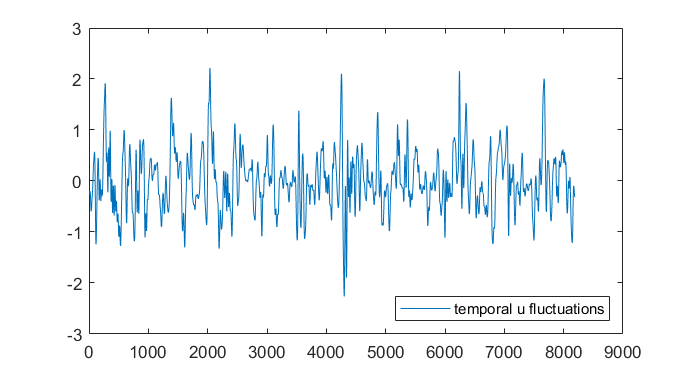

plot(u - mu_u,'DisplayName','temporal u fluctuations')
legend('show','location','southeast')
set(gcf,'position',[10,10,550,300])

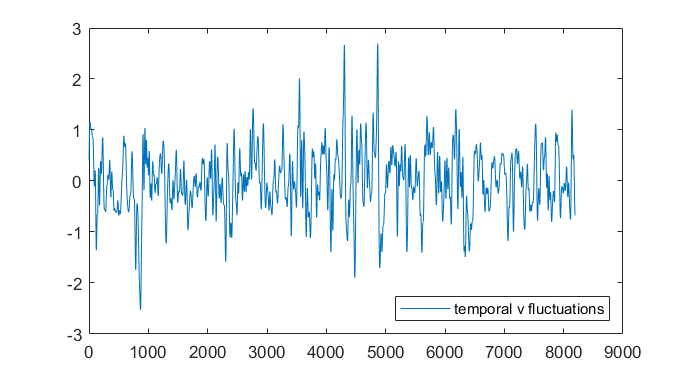

plot(v - mu_v,'DisplayName','temporal v fluctuations')
legend('show','location','southeast')

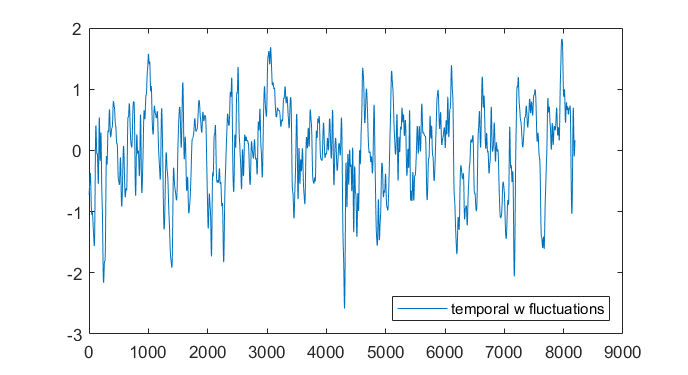

plot(w - mu_w,'DisplayName','temporal w fluctuations')
legend('show','location','southeast')

Below lines, will plot the span wise velocity fluctuations which are related to the first row in the stream wise direction in data set.

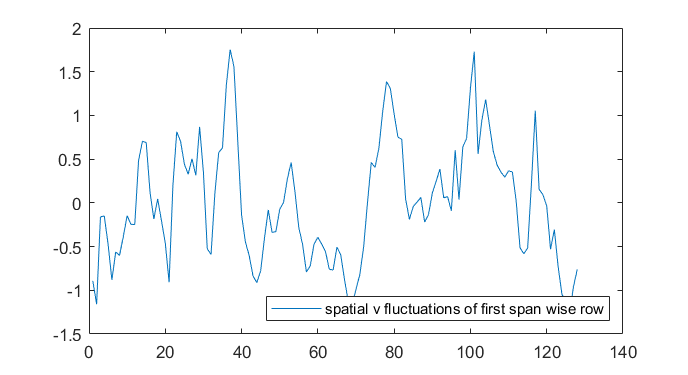

plot(vsp(1:256:length(vsp),1) - mu_vsp, ... 
    'DisplayName','spatial v fluctuations of first span wise row')
legend('show','location','southeast')

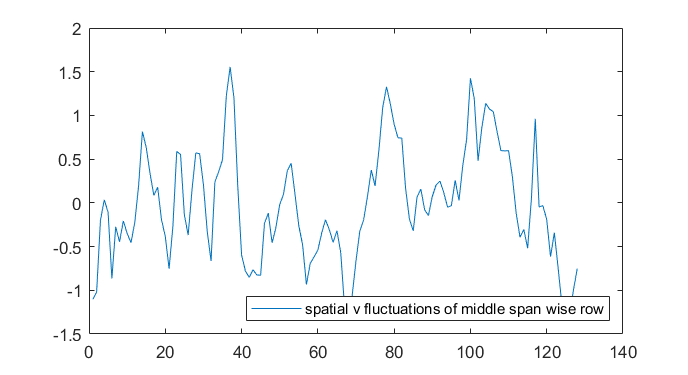

plot(vsp(128:256:length(vsp)-128,1) - mu_vsp, ...
    'DisplayName','spatial v fluctuations of middle span wise row')
legend('show','location','southeast')

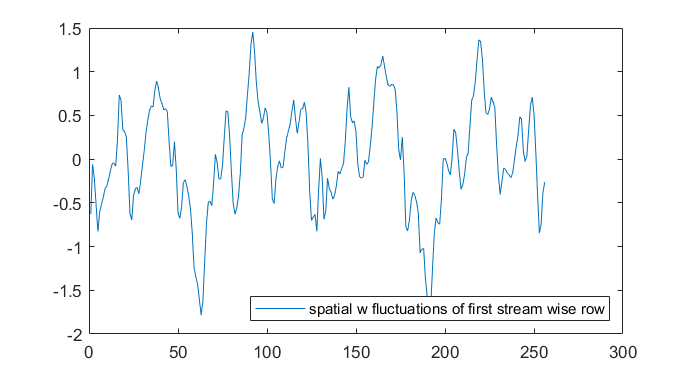

plot(wsp(1:256,1) - mean(wsp(1:256,1)), ...
    'DisplayName','spatial w fluctuations of first stream wise row')
legend('show','location','southeast')

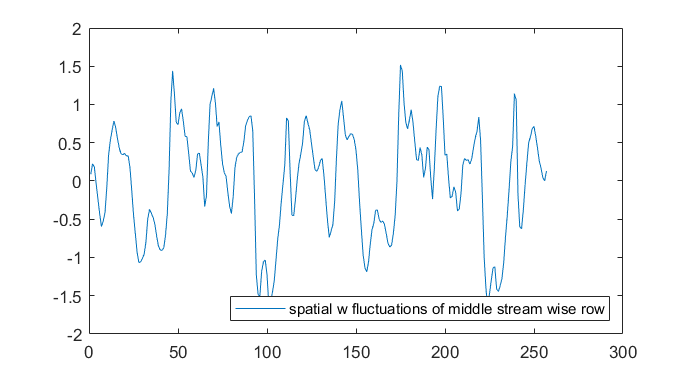

plot (wsp(length(wsp)/2 :length(wsp)/2 + 256,1) - ...
    mean(wsp(length(wsp)/2:length(wsp)/2 + 256,1)),...
    'DisplayName','spatial w fluctuations of middle stream wise row')
legend('show','location','southeast')

**It's clear from above figures, that the stream and span wise velocity component fluctuation's amplitude in the middle of both span and stream wise domain are weaker in cmparison with the first rows. Which should be considered in spatial data analysis.**

# Single PDFs

Probebility Density Functions are powerful tools in turbulence study. When there is the pdf of a velocity component, many other informations can be extracted from this probebility function. For example the power of wind can be evaluated during a year, if the PDF of the wind velocity exists. 

Some famous probebility distributions exist, that  can evaluate probebility density function of a phenomenon by usage of statistical moments, another application of statistical moments. A convinient distribution function which is applicable in turbulence is** the Gaussian distribution, which provides the PDF by means of fisrt and second statistical moments**.  $f(\tilde{u})$ which is defined as :


$$f(\tilde{u})={\frac {1}{\sigma {\sqrt {2\pi }}}}e^{-{\frac {1}{2}}\left({\frac {\tilde{u}-\mu }{\sigma }}\right)^{2}}}$$


Calculates the gaussian probebility distribution of a continues data, here there is some discrete data sets.

**Normalized histogram related to real PDFs** of data sets, will be compared by** the Gaussian and Wiebull distributions** of each data set. Real PDFs are normalized, because the integral of real histograms without normalization is more than one, consequently it can't show a real PDF. Below lines illustrate the normalized real probebility density function of DNS data. Also plot the Gaussian distribution and Wiebull one to provide a comparison between them.  

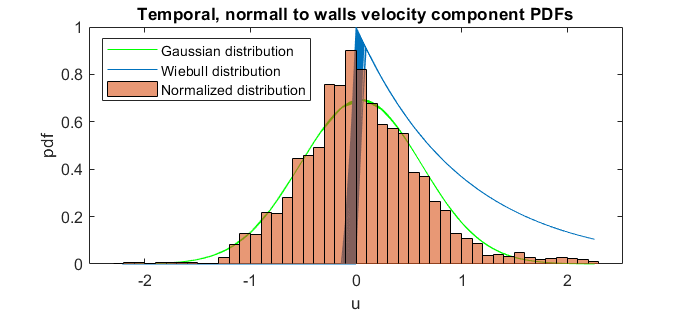

gm_u = gmdistribution(mu_u,sigma_u); u_pdf=pdf(gm_u,u);
plot( u, u_pdf,'green','DisplayName','Gaussian distribution')
hold on; plot(u,wblpdf(u),'DisplayName','Wiebull distribution')
histogram(u,'Normalization','pdf','DisplayName','Normalized distribution');hold off
title('Temporal, normall to walls velocity component PDFs')
legend('show','location','northwest'); xlabel('u') ;ylabel('pdf')
set(gcf,'position',[10,10,550,250])

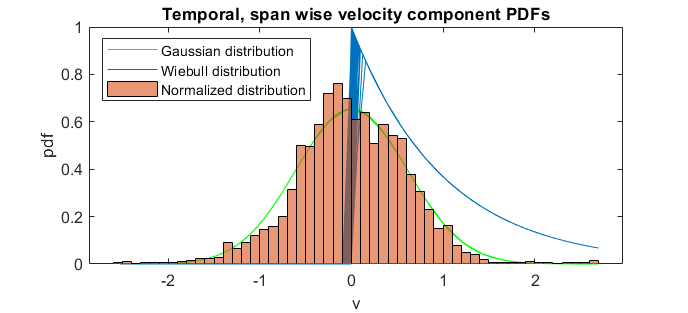

gm_v = gmdistribution(mu_v,sigma_v);
v_pdf=pdf(gm_v,v);
plot( v , v_pdf  ,'green','DisplayName','Gaussian distribution')
hold on
plot(v,wblpdf(v),'DisplayName','Wiebull distribution')
histogram(v,'Normalization','pdf','DisplayName','Normalized distribution')
hold off
legend('show','location','northwest')
title('Temporal, span wise velocity component PDFs')
xlabel('v'); ylabel('pdf')

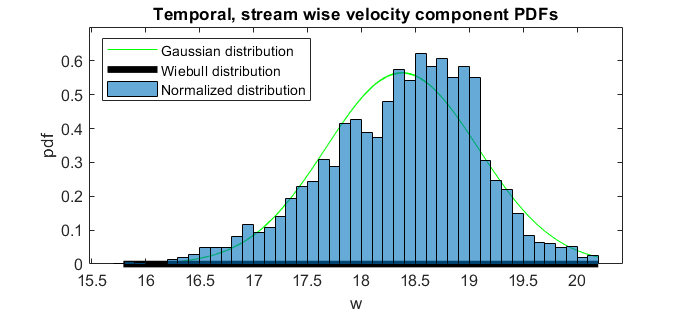

gm_w = gmdistribution(mu_w,sigma_w);
w_pdf=pdf(gm_w,w);
plot( w , w_pdf  ,'green','DisplayName','Gaussian distribution'); hold on
plot(w, wblpdf(w) ,'k','DisplayName','Wiebull distribution','LineWidth',4)
histogram(w,'Normalization','pdf','DisplayName','Normalized distribution')
hold off; legend('show','location','northwest')
title('Temporal, stream wise velocity component PDFs')
xlabel('w'); ylabel('pdf')

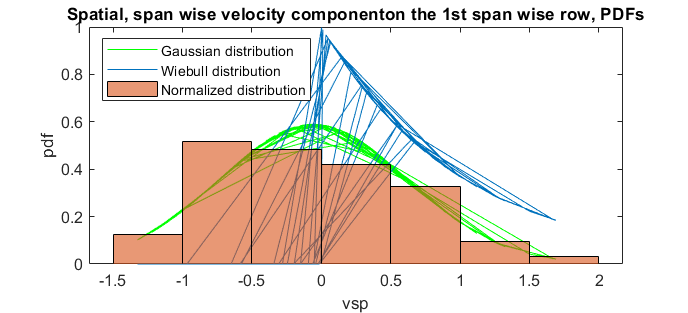

mu_vsp_first_raw = mean (vsp(1:256:length(vsp)));
sigma_vsp_first_raw = var ((vsp(1:256:length(vsp))));
gm_vsp_first_raw = gmdistribution(mu_vsp_first_raw,sigma_vsp_first_raw);
vsp_first_raw_pdf=pdf(gm_vsp_first_raw,vsp(1:256:length(vsp)));
plot( vsp(1:256:length(vsp)) , vsp_first_raw_pdf  ,...
    'green','DisplayName','Gaussian distribution'); hold on
plot(vsp(1:256:length(vsp)), wblpdf(vsp(1:256:length(vsp))) ,...
    'DisplayName','Wiebull distribution')
histogram(vsp(1:256:length(vsp)),...
'Normalization','pdf','DisplayName','Normalized distribution');hold off
legend('show','location','northwest')
title('Spatial, span wise velocity componenton the 1st span wise row, PDFs')
xlabel('vsp');ylabel('pdf')

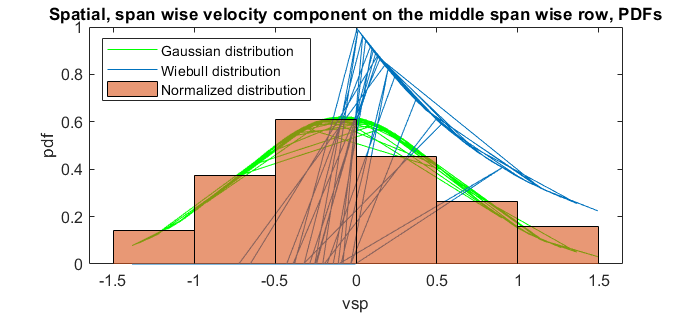

mu_vsp_middle_raw = mean(vsp(128:256:length(vsp)-127));
sigma_vsp_middle_raw = var(vsp(128:256:length(vsp)-127));
gm_vsp_middle_raw = gmdistribution(mu_vsp_middle_raw,sigma_vsp_middle_raw);
vsp_middle_raw_pdf=pdf(gm_vsp_middle_raw,vsp(128:256:length(vsp)-127));
plot( vsp(128:256:length(vsp)-127) , vsp_middle_raw_pdf  ,...
'green','DisplayName','Gaussian distribution'); hold on
plot(vsp(128:256:length(vsp)-127), wblpdf(vsp(128:256:length(vsp)-127)) ,...
    'DisplayName','Wiebull distribution')
histogram(vsp(128:256:length(vsp)-1),...
'Normalization','pdf','DisplayName','Normalized distribution'); hold off
legend('show','location','northwest')
title('Spatial, span wise velocity component on the middle span wise row, PDFs')
xlabel('vsp'); ylabel('pdf')

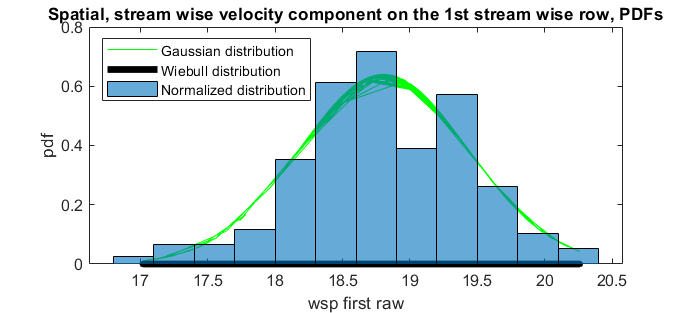

mu_wsp_first_raw = mean (wsp(1:256,1));
sigma_wsp_first_raw = var (wsp(1:256 ,1));
gm_wsp_first_raw = gmdistribution(mu_wsp_first_raw,sigma_wsp_first_raw);
wsp_first_raw_pdf=pdf(gm_wsp_first_raw,wsp(1:256 ,1));
plot( wsp(1:256, 1) , wsp_first_raw_pdf  ,...
'green','DisplayName','Gaussian distribution'); hold on
plot(wsp(1:256, 1), wblpdf(wsp(1:256, 1)) ,...
    'k','DisplayName','Wiebull distribution','LineWidth',4)
histogram(wsp(1:256, 1),'Normalization','pdf','DisplayName','Normalized distribution')
hold off; legend('show','location','northwest')
title('Spatial, stream wise velocity component on the 1st stream wise row, PDFs')
xlabel('wsp first raw'); ylabel('pdf')

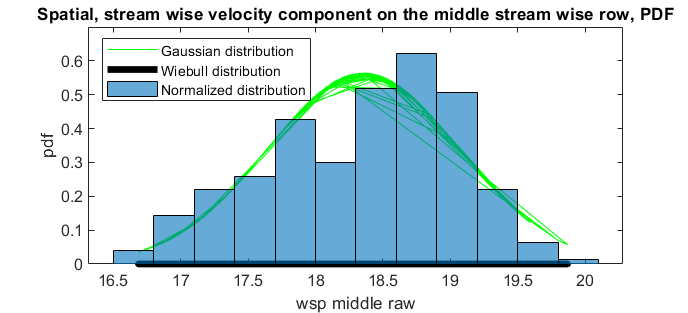

mu_wsp_middle_raw = mean (wsp(length(wsp)/2:length(wsp)/2 + 256,1));
sigma_wsp_middle_raw = var (wsp(length(wsp)/2:length(wsp)/2 + 256,1));
gm_wsp_middle_raw = gmdistribution(mu_wsp_middle_raw,sigma_wsp_middle_raw);
wsp_middle_raw_pdf=...
    pdf(gm_wsp_middle_raw,wsp(length(wsp)/2:length(wsp)/2 + 256,1));
plot( wsp(length(wsp)/2:length(wsp)/2 + 256,1) , wsp_middle_raw_pdf  ,...
    'green','DisplayName','Gaussian distribution'); hold on
plot(wsp(length(wsp)/2:length(wsp)/2 + 256,1),...
    wblpdf(wsp(length(wsp)/2:length(wsp)/2 + 256,1))...
    ,'k','DisplayName','Wiebull distribution','LineWidth',4)
histogram(wsp(length(wsp)/2:length(wsp)/2 + 256,1),...
'Normalization','pdf','DisplayName','Normalized distribution'); hold off
legend('show','location','northwest')
title('Spatial, stream wise velocity component on the middle stream wise row, PDF')
xlabel('wsp middle raw'); ylabel('pdf')

As mentioned before, from above single PDFs it's clear that the Gaussian distribution is very closer than Wiebul distribution to real normalized PDFs, in turbulence study.  

## CDFs

It's well known that cumulative density function is the integrated of the density probebility function. So one can be eveluated from other. Here CDFs related to velocity components are plotted.

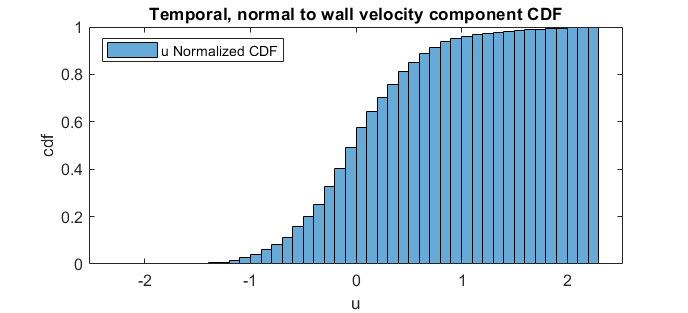

histogram(u,'Normalization','cdf','DisplayName','u Normalized CDF')
legend('show','location','northwest'); xlabel('u'); ylabel('cdf');
title('Temporal, normal to wall velocity component CDF')

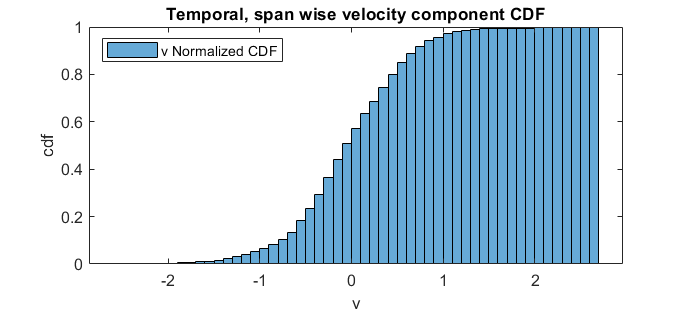

histogram(v,'Normalization','cdf','DisplayName','v Normalized CDF')
legend('show','location','northwest'); xlabel('v'); ylabel('cdf');
title('Temporal, span wise velocity component CDF')

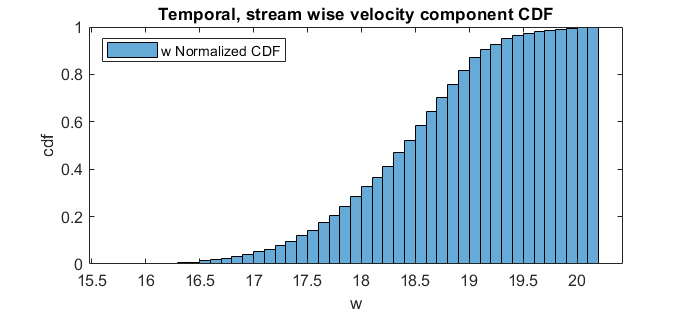

histogram(w,'Normalization','cdf','DisplayName','w Normalized CDF')
legend('show','location','northwest'); xlabel('w'); ylabel('cdf')
title('Temporal, stream wise velocity component CDF')

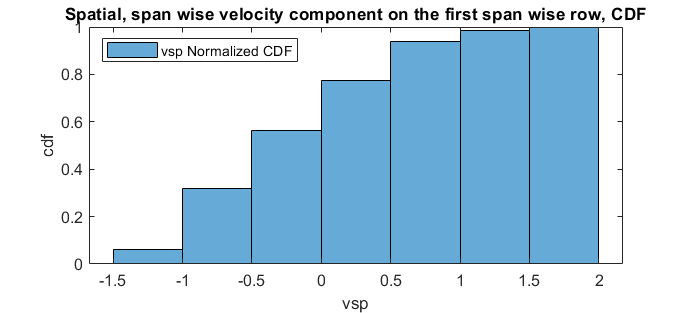

histogram(vsp(1:256:length(vsp)),'Normalization','cdf',...
    'DisplayName','vsp Normalized CDF')
legend('show','location','northwest'); xlabel('vsp'); ylabel('cdf') 
title(...
'Spatial, span wise velocity component on the first span wise row, CDF')

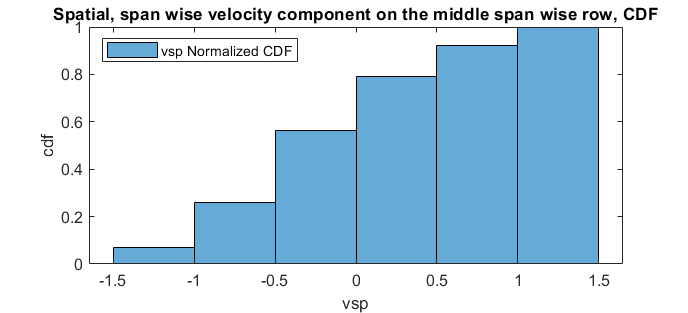

histogram(vsp(128:256:length(vsp)-127),'Normalization',...
    'cdf','DisplayName','vsp Normalized CDF')
legend('show','location','northwest'); xlabel('vsp'); ylabel('cdf')
title('Spatial, span wise velocity component on the middle span wise row, CDF')

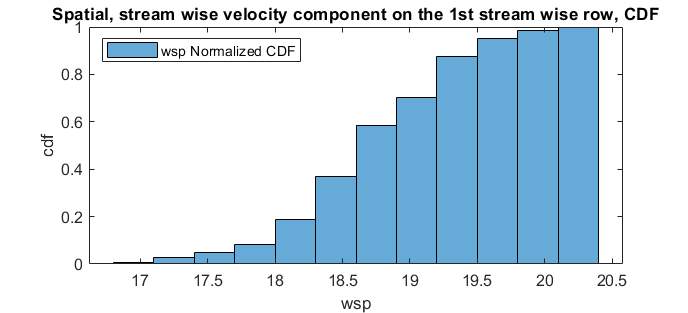

histogram(wsp(1:256, 1),'Normalization','cdf','DisplayName','wsp Normalized CDF')
legend('show','location','northwest'); xlabel('wsp'); ylabel('cdf')
title('Spatial, stream wise velocity component on the 1st stream wise row, CDF') 

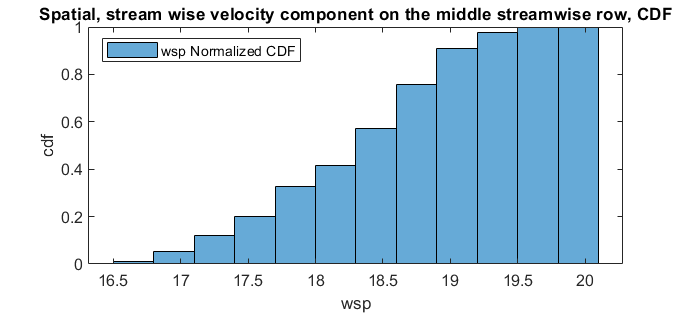

histogram(wsp(length(wsp)/2:length(wsp)/2 + 256,1),...
    'Normalization','cdf','DisplayName','wsp Normalized CDF')
legend('show','location','northwest'); xlabel('wsp'); ylabel('cdf') 
title('Spatial, stream wise velocity component on the middle streamwise row, CDF')

## Joint PDFs

The joint probability density function (joint pdf) is a function used to characterize **the probability distribution of several variables**, which together form a vector.

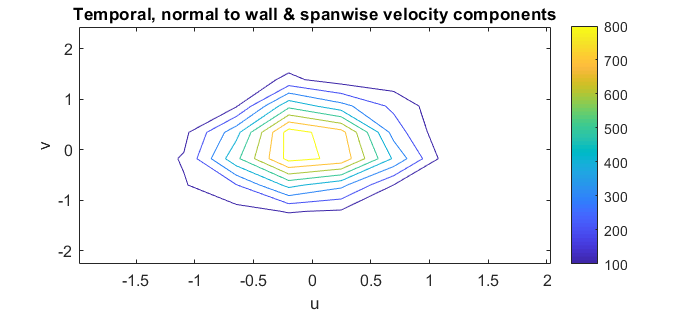

[n,c]=hist3([tab_data(:,1),tab_data(:,2)]); contour(c{1},c{2},n);
title('Temporal, normal to wall & spanwise velocity components');
xlabel('u'); ylabel('v'); colorbar;

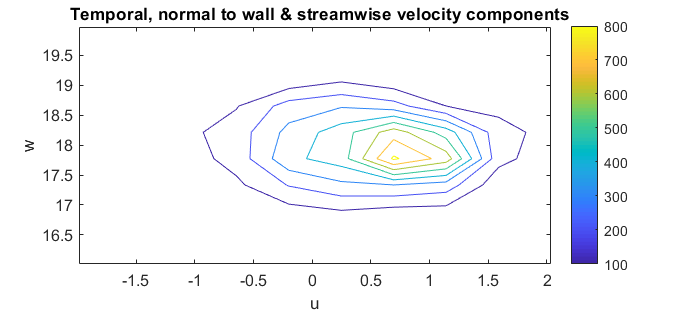

[n,c]=hist3([tab_data(:,1),tab_data(:,3)]); contour(c{1},c{2},n);
title('  Temporal, normal to wall & streamwise velocity components');
xlabel('u'); ylabel('w'); colorbar;

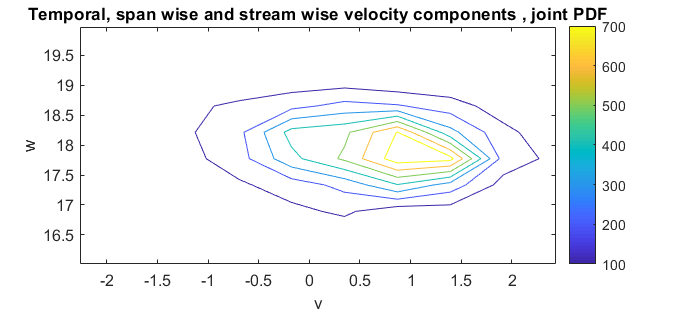

[n,c]=hist3([tab_data(:,2),tab_data(:,3)]); contour(c{1},c{2},n);
title('Temporal, span wise and stream wise velocity components , joint PDF');
xlabel('v');ylabel('w');colorbar;

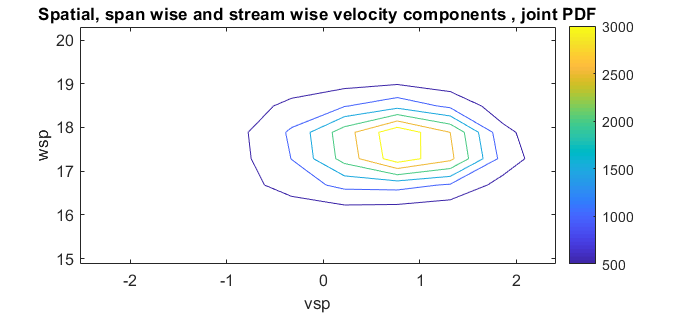

[n,c]=hist3([tab_data_sp(:,1),tab_data_sp(:,2)]); contour(c{1},c{2},n);
title('Spatial, span wise and stream wise velocity components , joint PDF');
xlabel('vsp'); ylabel('wsp'); colorbar;

# Correlations

Correlation factor which is defined as : 


$$C_{ij} =\sqrt {\frac{\overline{u_i u_j}}{\overline{u_i^2 . {u_i^2 }}}$$


Represents the correlation between $u_i \, , u_j$ (fluctuatins) . Note that if $C_{ij} = \pm 1$, the correlation is said to be perfect. Each variable, of course, is perfectly correlated with itself. 

Here the corrcoef returns a $2 x 2$ symmetric tensor for each pair of fluctuating velocity components, the diagonal entries equal to one because display self correlation factors. 

corrcoef(u - mu_u,v -mu_v)

ans =     1.0000    0.0248
    0.0248    1.0000


corrcoef(w - mu_w,u -mu_u)

ans =     1.0000   -0.1673
   -0.1673    1.0000


corrcoef(w - mu_w,v -mu_v)

ans =     1.0000   -0.1232
   -0.1232    1.0000


Here evaluated correlation factors for each pair of** temporal **data set come together in a complete correlation tensor.

cf_te = [1.0000 -0.1673 -0.1232
    -0.1673    1    0.0248
    -0.1232 0.0248     1  ]

cf_te =     1.0000   -0.1673   -0.1232
   -0.1673    1.0000    0.0248
   -0.1232    0.0248    1.0000


Below line calculates the **spatial** velocity components correlation factor tensor.

cf_sp = corrcoef(vsp - mu_vsp,wsp -mu_wsp)

cf_sp =     1.0000    0.0009
    0.0009    1.0000


## Reynolds stress tensor

The contribution of the turbulent motion to the mean stress tensor is designated by the symbol $\tau_{ij$ which is defined as :


$$\tau_{ij}= -\overline{\rho u_{i} u_{j}}$$


and is called **Reynolds stress tensor **which is symmetric. 

The diagonal components of that are **normal stresses** (pressures), which In many flows contribute little to the transport of mean momentum. However The off-diagonal components are **shear stresses**; they play a dominant role in the theory of mean momentum transfer by turbulent motion.  First shear stress entries, then normal stress ones are evaluated by below lines. Then shear stress tensor will be built, for both temporal and spatial data sets.

mean ((u - mu_u) .* (v - mu_v))

ans = 0.0087

mean ((w - mu_w) .* (u - mu_u))

ans = -0.0678

mean ((w - mu_w) .* (v - mu_v))

ans = -0.0530

mean ((w - mu_w) .^2)

ans = 0.4978

mean ((u - mu_u) .^2 )

ans = 0.3300

mean ((v - mu_v) .^2)

ans = 0.3717

%Reynolds stress tensor of temporal data set
Re_st_te = [ 0.4978 -0.0678 -0.0530
    -0.0678  0.3300  0.0087
    -0.0530  0.0087  0.3717 ]

Re_st_te =     0.4978   -0.0678   -0.0530
   -0.0678    0.3300    0.0087
   -0.0530    0.0087    0.3717


a = mean((wsp - mu_wsp) .* (vsp - mu_vsp))  

a = 4.4925e-04

b = mean((wsp - mu_wsp) .^2 ) 

b = 0.6661

c = mean((vsp - mu_vsp) .^2 )

c = 0.3978

% Re stress tensor for spatial data set
Re_st_sp = [b a; a c]

Re_st_sp =     0.6661    0.0004
    0.0004    0.3978


## Auto correlation

To describe the evolution of a fluctuating function, a question should be answered, how the values of $u$ at different times are related. The correlation  between $u(t)$ and $u(t+T)$is called 

the autocorrelation. Because we are working with stationary variables, the autocorrelation gives no information on the origin of time.The autocorrelation shows if the spatial domain dimensions are not sufficient, here autocorrelation for temporal data sets are provided. The **lag** refers to how far the series are offset, and its sign determines which series is shifted. Note that as the lag increases, the number of possible matches decreases because the series hang out at the ends and do not overlap. The value of the lag with the highest correlation coefficient represents the best fit between the two series.  The lag times the sampling interval gives the duration by which one series leads or trails the other--how long it takes the effect to propagate from one variable to the other.  If you have hourly data and the best lag in 12, the time difference between the two series is 12 hours.

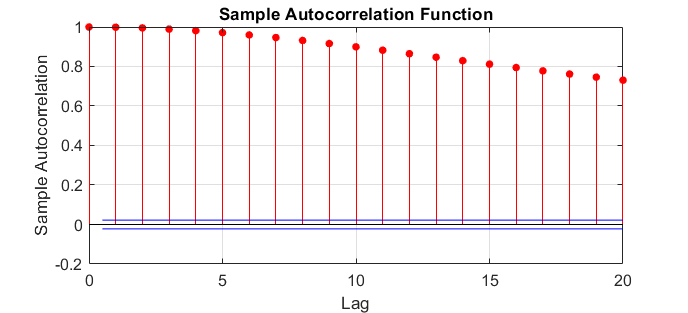

autocorr(w- mu_w)

For stream wise velocity component fluctuations, the autocorrelation function varies smoothly, it seems that spatial domain length in longitudinal direction is sufficient.

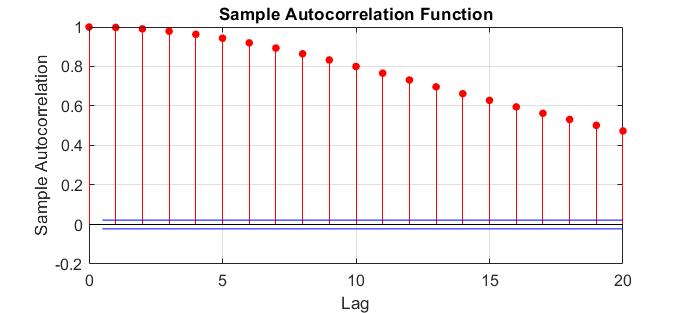

autocorr(u- mu_u)

For normal to wall velocity component fluctuations, the autocorrelation function has a sharper trend in comparison with stream wise one, so that spatial domain length in normal to wall direction seems insufficient.

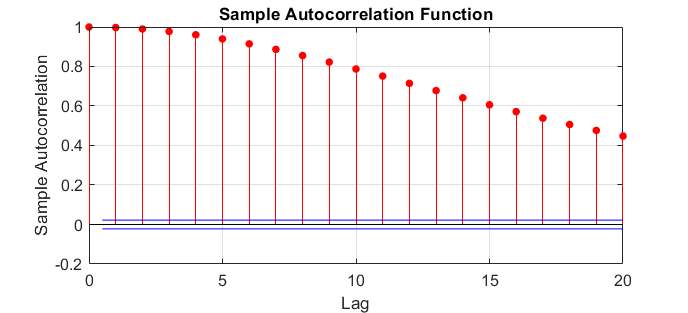

autocorr(v- mu_v)

Similarly, span wise velocity component fluctuations autocorrelation has a sharp slope which declares that the span wise length of the computational domain is insufficient.

## Cross correlation

Cross-correlation is a measurement that tracks the movements of two or more sets of time series data relative to one another. It is used to compare multiple time series and objectively determine how well they match up with each other and, in particular, at what point the best match occurs. Below line plots the cross correlation between the temporal normal to walls and stream wise velocity components.

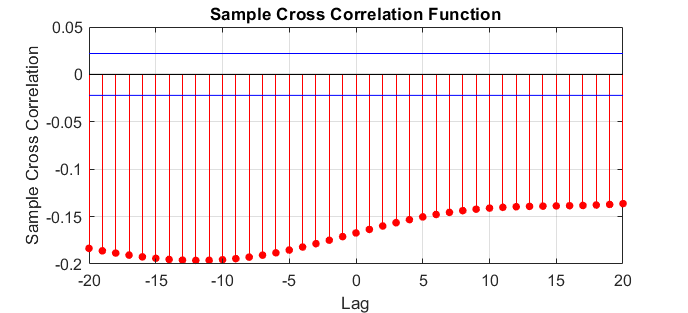

crosscorr(u,w)

 The cross correlation between the temporal normal to walls and span wise velocity components is drawn underneath.

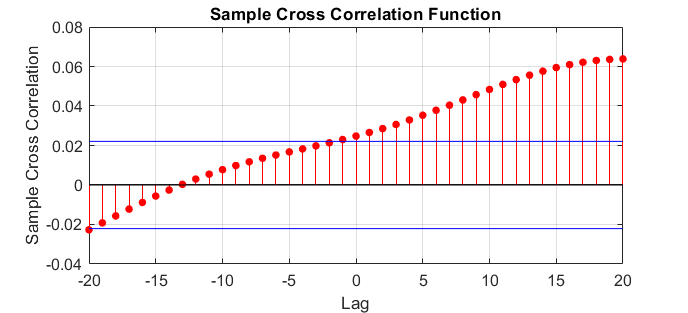

crosscorr(u,v)

 The cross correlation between the temporal normal to walls and stream wise velocity components is shown below.

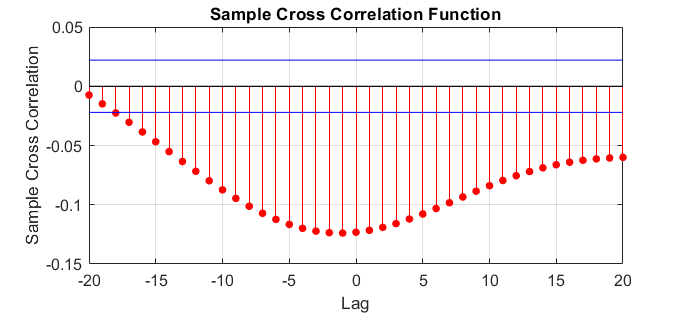

crosscorr(v,w)

From above crosscorrelation figures, it's clear that the correlation factor between normal to walls and and span wise velocity components is lower than others. May be this result is effect of walls.

## Spatial crosscorrelation 

As is evidence number of nodes differs for each spatial direction in computational domain, so if there is an intrest to evaluate cross correlation between, for example, first raws of stream wise and span wise nodes. The stream wise data should be half of whatever is in real. This action is done to plot 2D energy spectrum, but here the crosscorrelation related to all spatial data is plotted by below line.

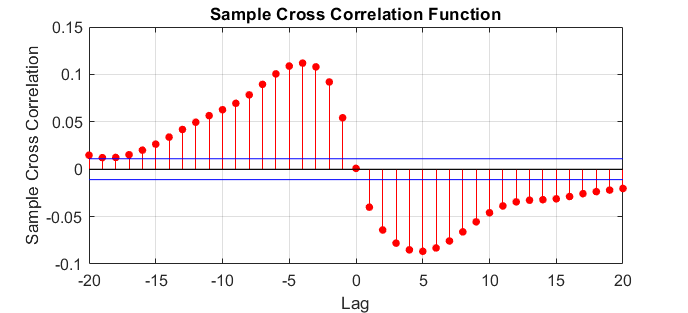

crosscorr(wsp,vsp)

In above figure lag doesn't mean as whatever was before, because it refers to spatial informations.

# Energy spectra

## 1D spectra

A turbulent flow varies randomly in all two space directions and in time. Experimental measurements, say of velocity, may be made along a straight line at a fixed time, at a fixed point as a function of time, or following a moving fluid point as a function of time. 

A measurement of this kind generates a random function of position or time. If the function is stationary or homogeneous, an autocorrelation can be formed and a spectrum can  be computed. If the autocorrelation is a function of a time interval, the transform variable is a frequency; if the autocorrelation is a function of a spatial separation, the transform variable is a 

wave number .Spectra obtained in this way are called one-dimensional spectra because the measurements producing them were taken in one dimension.

## Temporal data velocity spectra

Here the energy spectrums, related to temporal data set are plotted. Note that an arbitrary time interval is chosen to evaluate a frequency range.

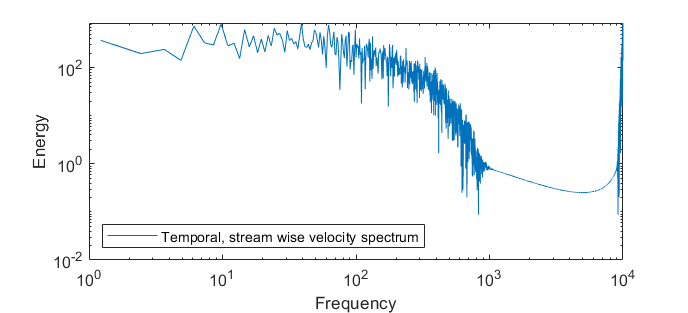

dt=0.0001;% time step
t_final=(8192-1)*dt;
t=0:dt:t_final;
f_max = 1/dt;
df=f_max/(8192-1);
f=0:df:f_max;
loglog(f,abs(fft((w- mu_w) .^2)),...
    'DisplayName','Temporal, stream wise velocity spectrum');
legend('show','Location','southwest');
xlabel('Frequency'); ylabel('Energy');

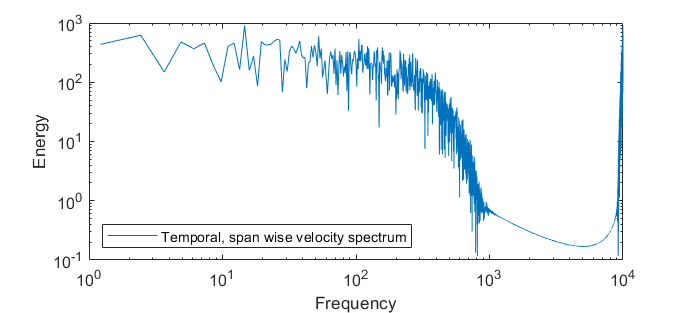

loglog(f,abs(fft((v- mu_v) .^2)),'DisplayName'...
    ,'Temporal, span wise velocity spectrum');
legend('show','Location','southwest'); xlabel('Frequency'); ylabel('Energy');

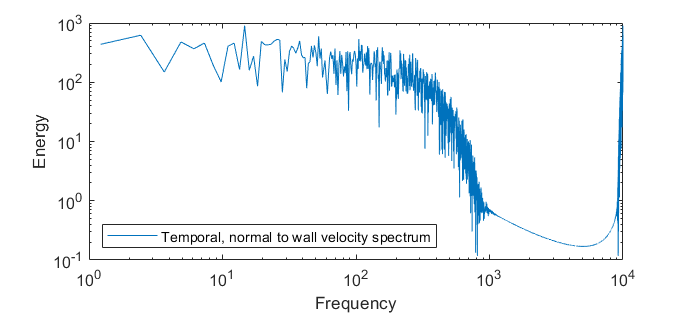

loglog(f,abs(fft((v- mu_v) .^2)),...
    'DisplayName','Temporal, normal to wall velocity spectrum');
legend('show','Location','southwest'); xlabel('Frequency'); ylabel('Energy');

## Spatial data energy Spectra

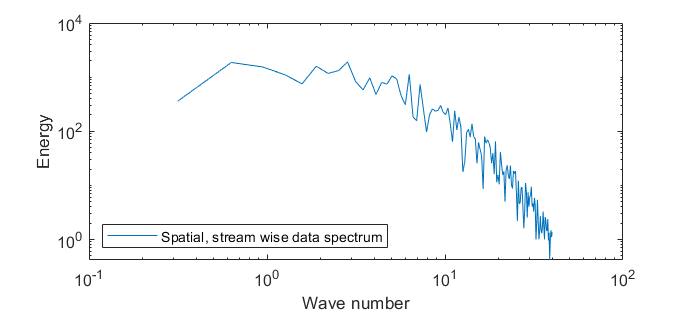

dz= 0.025;
nz = length(wsp)/256;
z = (0:nz -1) * dz;
max_wave_n_z = 1/dz;
dwave_n_z = max_wave_n_z/(nz-1);
wave_n_z = 0: dwave_n_z : 1/dz;
Wsp_spectrum_real_part= abs(fft((wsp - mu_wsp).^2));
loglog(wave_n_z,Wsp_spectrum_real_part(1:128,1),...
    'DisplayName','Spatial, stream wise data spectrum');
legend('show','Location','southwest'); xlabel('Wave number'); ylabel('Energy');

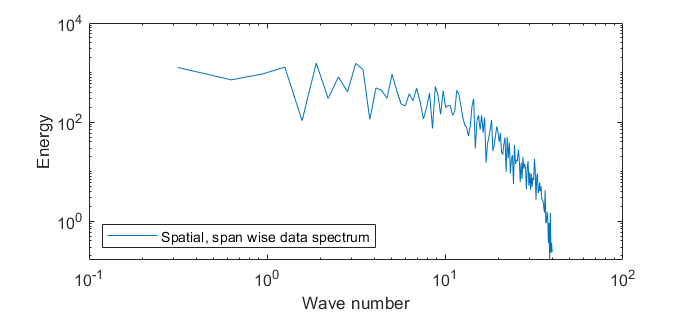

dy = 0.025;
ny = length(vsp)/256;
y = (0:ny -1) * dy;
max_wave_n_y = 1/dy;
dwave_n_y = max_wave_n_y/(ny-1);
wave_n_y = 0: dwave_n_y : 1/dy;
vsp_spectrum_real_part=abs(fft((vsp - mu_vsp).^2));
loglog(wave_n_y,vsp_spectrum_real_part(1:128,1),...
    'DisplayName','Spatial, span wise data spectrum');
legend('show','Location','southwest'); xlabel('Wave number'); ylabel('Energy');

## 2D spectra

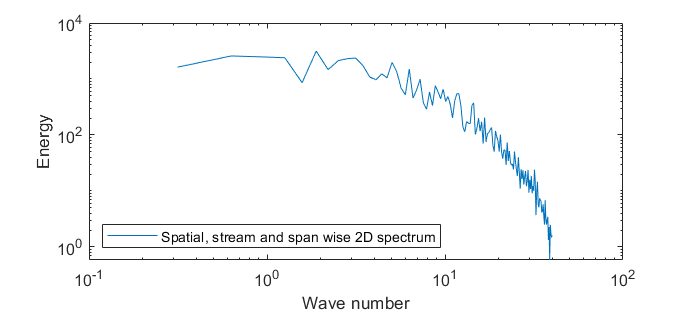

sum_of_wsp_vsp_spectum_real_part= Wsp_spectrum_real_part + vsp_spectrum_real_part;
max_wave_n_y = 1/dy;
dwave_n_y = max_wave_n_y/(ny-1);
wave_n_y = 0: dwave_n_y : 1/dy;
loglog(wave_n_y,sum_of_wsp_vsp_spectum_real_part(1:128,1),...
    'DisplayName','Spatial, stream and span wise 2D spectrum');
legend('show','Location','southwest');xlabel('Wave number'); ylabel('Energy');